%{
This notebook predicts if the designed cell will meet the customer
requirement for lifetime (80 % retention after 50 cycles). The capacity 
retention is projected based on a model that assumes cell degradation
occurs exclusively due to SEI formation.

As such, the model considers anode active material loss and lithium
inventory loss as the two degradation modes (with no cathode active
material loss). Once again, only losses due to the mechanism of SEI
formation are considered.

This notebook demonstrates the ability to model full cell capacity
retention based on understanding and applying the equations that dictate 
each degradation mechanism. The model is derived from:

Lee et al. (2020), Electrode State of Health Estimation for Lithium 
Ion Batteries Considering Half-cell Potential Change Due to Aging

*Note that only thermodynamic capacity is considered here, capacity lost
due to increases in internal cell resistance are ignored.
%}

% Load anode data
tableN = readtable("si_anode.csv");
cVecN = table2array(tableN(:,"capacity"));
vVecN = table2array(tableN(:,"voltage"));

[thetaVecN, vThetaVecN] = normalizeCapacity(cVecN, vVecN);

% Load cathode data
tablePNMC = readtable("nmc_cathode.csv");
cVecP = table2array(tablePNMC(:,"capacity"));
vVecP = table2array(tablePNMC(:,"voltage"));

[thetaVecP, vThetaVecP] = normalizeCapacity(cVecP, vVecP);

%plot(thetaVecN, vThetaVecN, 'r--', thetaVecP, vThetaVecP, 'b--')

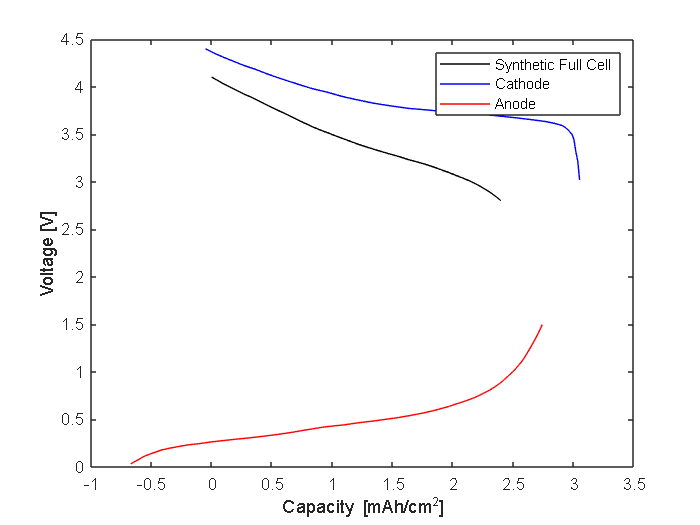

% Set degradation parameters (ESOH)
cEff = 0.996;
chargeDir = "dchg";
vMin = 2.8; % V
vMax = 4.1; % V

npRatio = 1.1;
cNFresh = 3.41; % mAh/cm^2
cPFresh = cNFresh / npRatio; % mAh/cm^2
x0Fresh = 0;
y0Fresh = 0.9;

% Calculate and plot full cell modelled voltage
[~, ~, cLiFresh] = compInvFromESOH(cNFresh, cPFresh, x0Fresh, y0Fresh);

[cVecNModel, vVecNModel, cVecPModel, vVecPModel, cVecFullModel, vVecFullModel] = combineHalfCells(thetaVecN, ...
    vThetaVecN, thetaVecP, vThetaVecP, cNFresh, cPFresh, x0Fresh, y0Fresh, vMin, vMax, chargeDir);
figure(1)
plotHalfCellModel(cVecNModel, vVecNModel, cVecPModel, vVecPModel, cVecFullModel, vVecFullModel, "-")
legend(["Synthetic Full Cell", "Cathode", "Anode"])
title("")

% Determine capacity fade

% Set constants
anodePorosity = 0.35;
anodeDensity = 1.13; % g/cm^3
anodeLoading = 4.112; % mg/cm^2
anodeElyteV = anodeLoading/1000/anodeDensity*anodePorosity; % mL/cm^2

cLiVec = cLiFresh;
cNVec = cNFresh;
cPVec = cPFresh;
x0Vec = x0Fresh;
y0Vec = y0Fresh;
cFullVec = max(cVecFullModel);
anodeElyteVVec = anodeElyteV;

LLIPerCycle = lithiumLoss(cEff);
LAMnPerCycleVec = [];


% Loop over 100 cycles, calculating degradation state at each cycle
% For degradation state, include half cell and full cell capacities, ESOH
% parameters, electrolyte volume and LAMn
for i = 1:100
    [LAMnPerCycle, newAnodeElyteV] = anodeLoss(cEff, cFullVec(i), anodeElyteVVec(i));
    newCN = cNVec(i) - cNVec(i) * LAMnPerCycle;
    newCLi = cLiVec(i) - cLiVec(i) * LLIPerCycle;
    [~, ~, newX0, newY0] = esohFromCompInv(newCN, cPVec(i), newCLi);

    [cVecNModel, ~, cVecPModel, ~, cVecFullModel, ~] = combineHalfCells(thetaVecN, vThetaVecN, ...
        thetaVecP, vThetaVecP, newCN, cPVec(i), newX0, newY0, vMin, vMax, chargeDir);

    cLiVec = [cLiVec newCLi];
    cNVec = [cNVec newCN];
    cPVec = [cPVec cPVec(i)];
    x0Vec = [x0Vec newX0];
    y0Vec = [y0Vec newY0];
    cFullVec = [cFullVec max(cVecFullModel)];
    anodeElyteVVec = [anodeElyteVVec newAnodeElyteV];
    LAMnPerCycleVec = [LAMnPerCycleVec LAMnPerCycle];

end

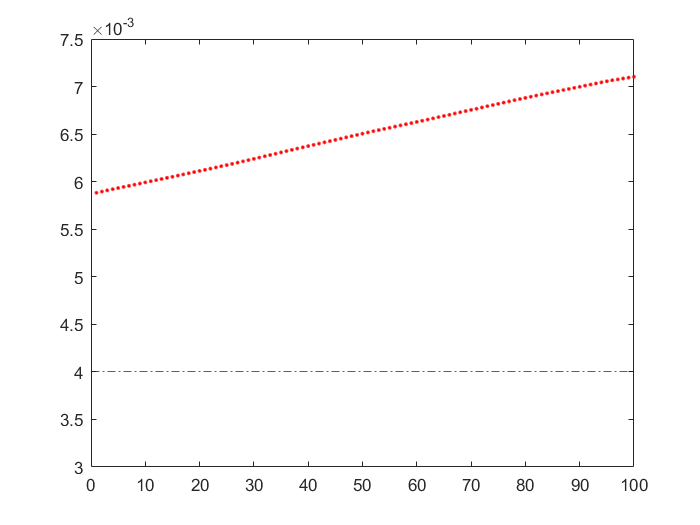

% Plot LAMn compared to coulombic efficiency to understand the effect of
% excess electrolyte
plot(LAMnPerCycleVec, 'r.')
hold on
yline(1-cEff, 'b-.')
ylim([3e-3, 7.5e-3])
hold off

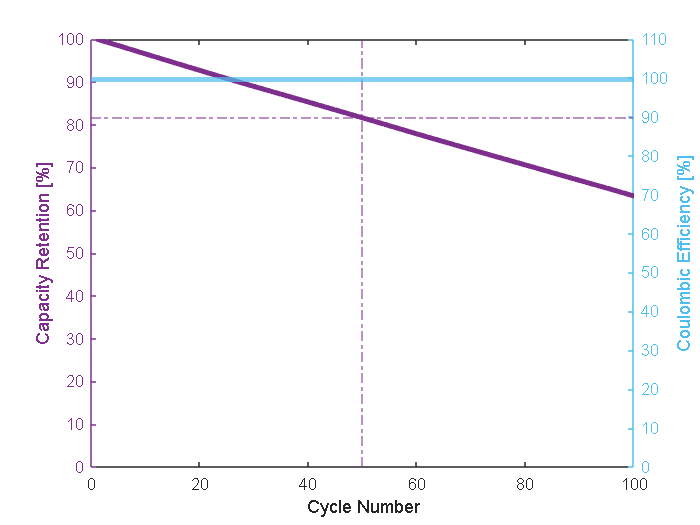

% Plot capacity retention and coulombic efficiency over 100 cycles based on
% the developed model (of LAMn and LLI due to SEI formation)
capRetention = cFullVec / max(cFullVec) *100;

figure(2)
yyaxis("left")
plot(capRetention, color="#7E2F8E", LineWidth=3)
ylabel("Capacity Retention [%]")
xlabel("Cycle Number")
ylim([0,100]);
xlim([0,100]);
ax = gca;
ax.YColor = "#7E2F8E";
yline(capRetention(50), "-.", color="#7E2F8E")
xline(50, "-.", color="#7E2F8E")

yyaxis("right")
yline(cEff*100, color="#4DBEEE", LineWidth=3)
ylim([0,110]);
ylabel("Coulombic Efficiency [%]")
ax = gca;
ax.YColor = "#4DBEEE";

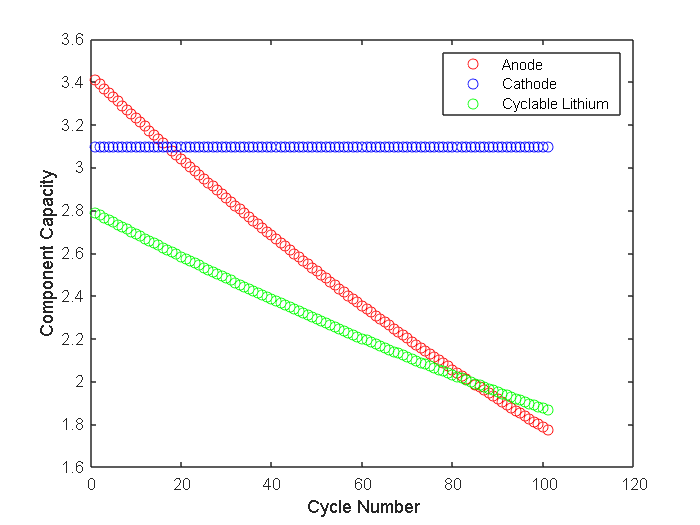


% Plot each of the component capacities as a function of cycle number
figure(3)
plot(cNVec, "ro")
hold on
plot(cPVec, "bo")
plot(cLiVec, "go")
ylabel("Component Capacity")
xlabel("Cycle Number")
legend(["Anode", "Cathode", "Cyclable Lithium"])
hold off

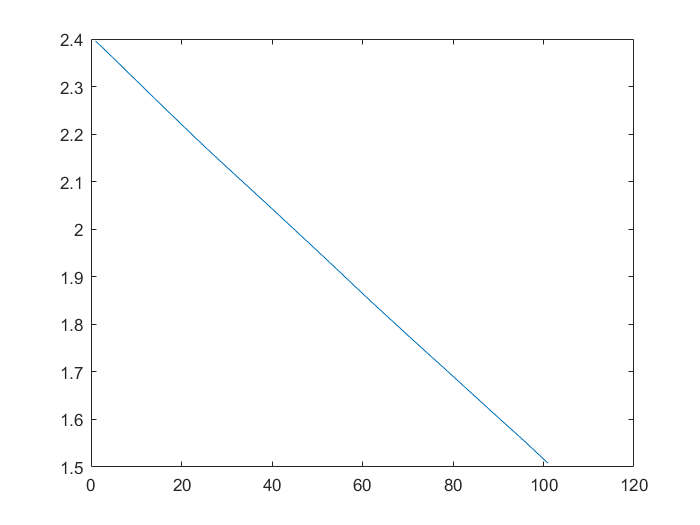


figure(4)
plot(cFullVec)